# Tutorial March 19 Exercise 1

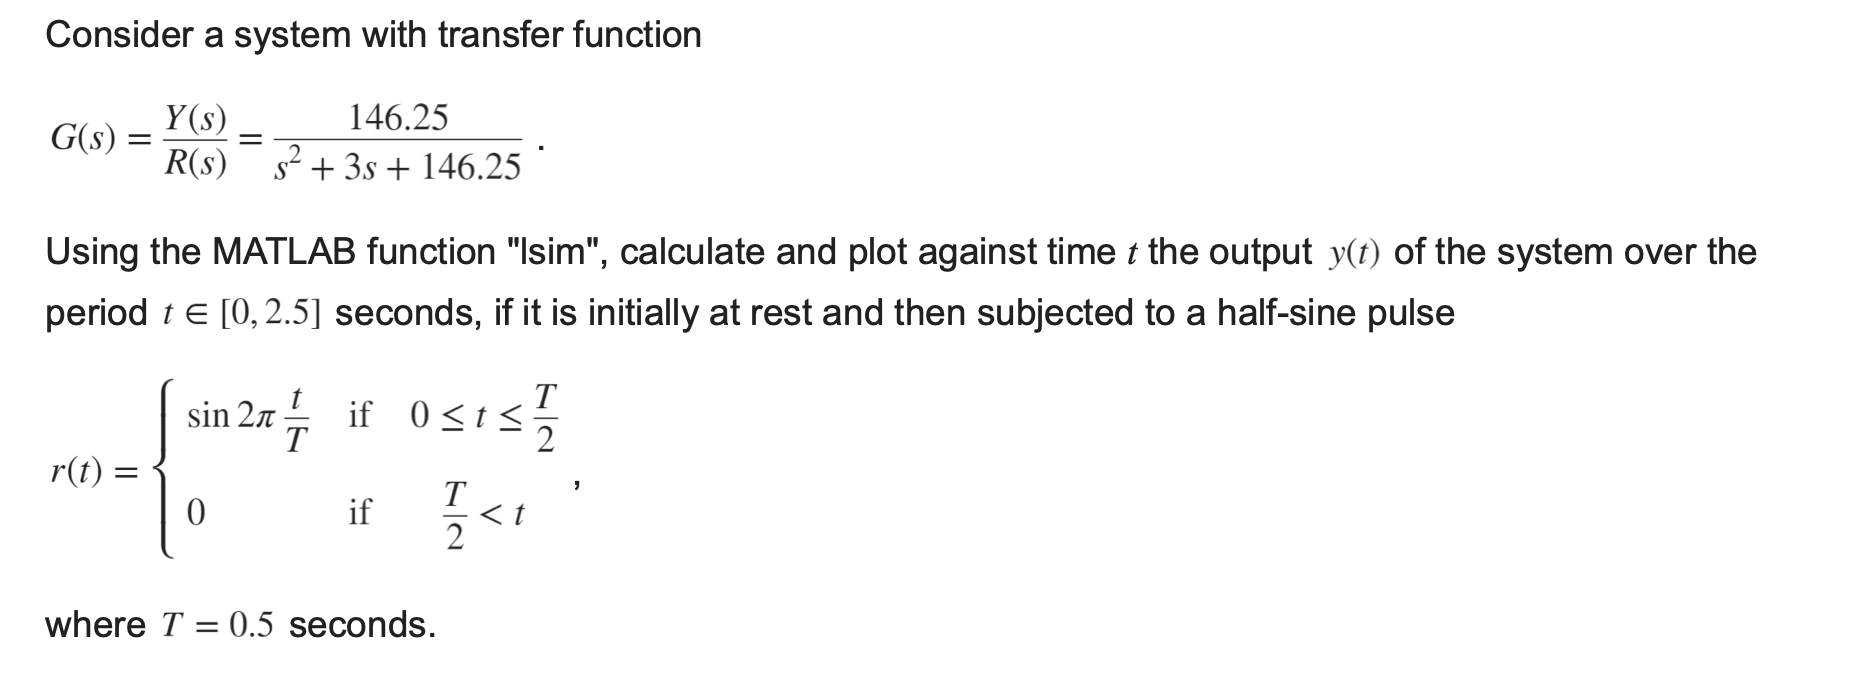

clearvars, close all, clc
G = tf(146.25, [1, 3, 146.25])


G =
 
        146.2
  -----------------
  s^2 + 3 s + 146.3
 
Continuous-time transfer function.


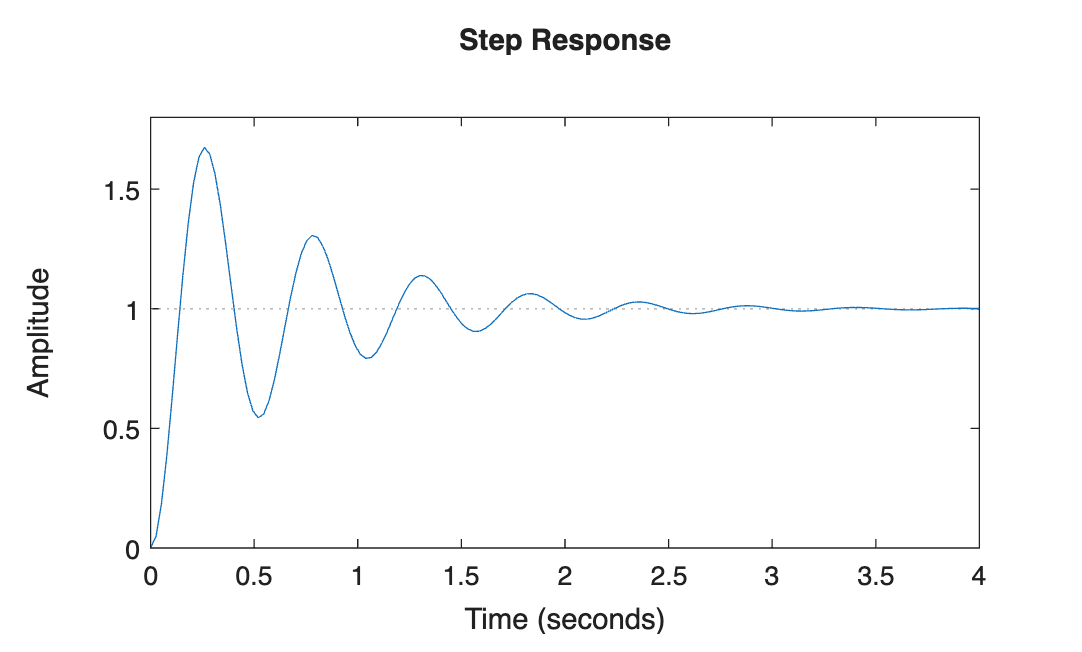


figure(1)
step(G)


pT = 0.5

pT = 0.5000

[r1,t1] = gensig('sine',pT,pT/2);  % gensig(type, tau, Tf)

usage of gensig

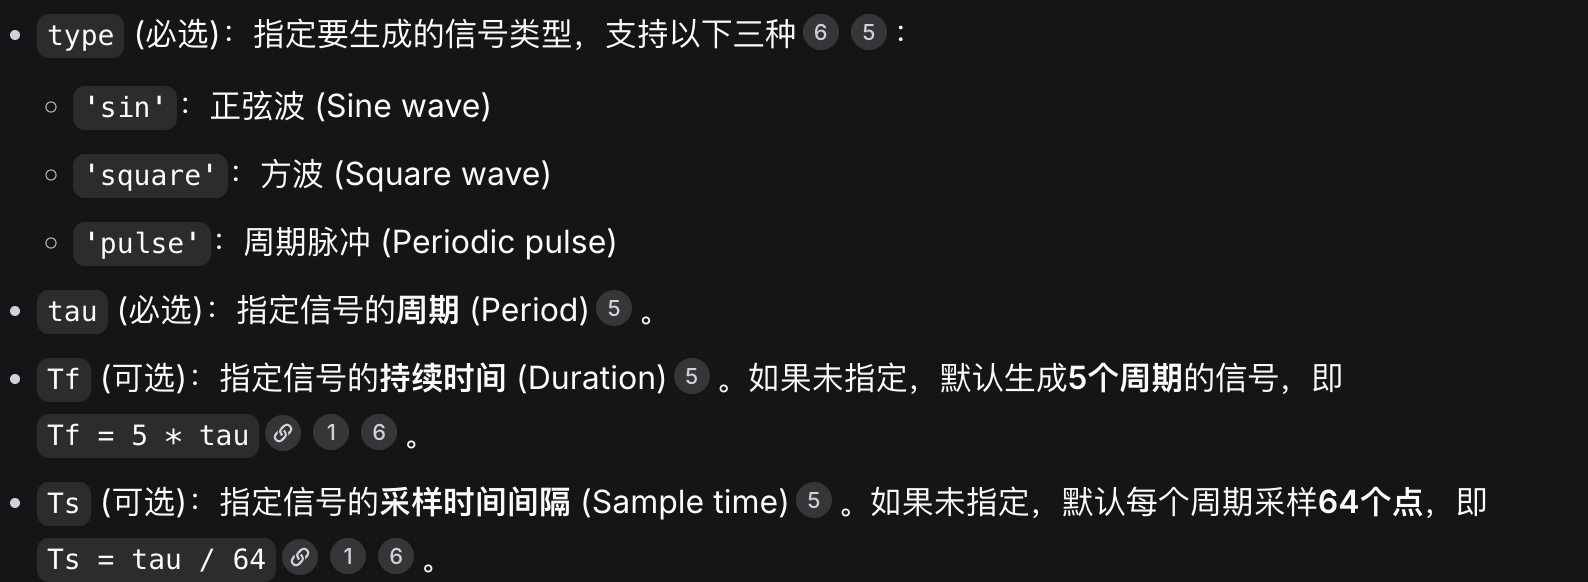

delt = t1(2)-t1(1) %采样时间

delt = 0.0078

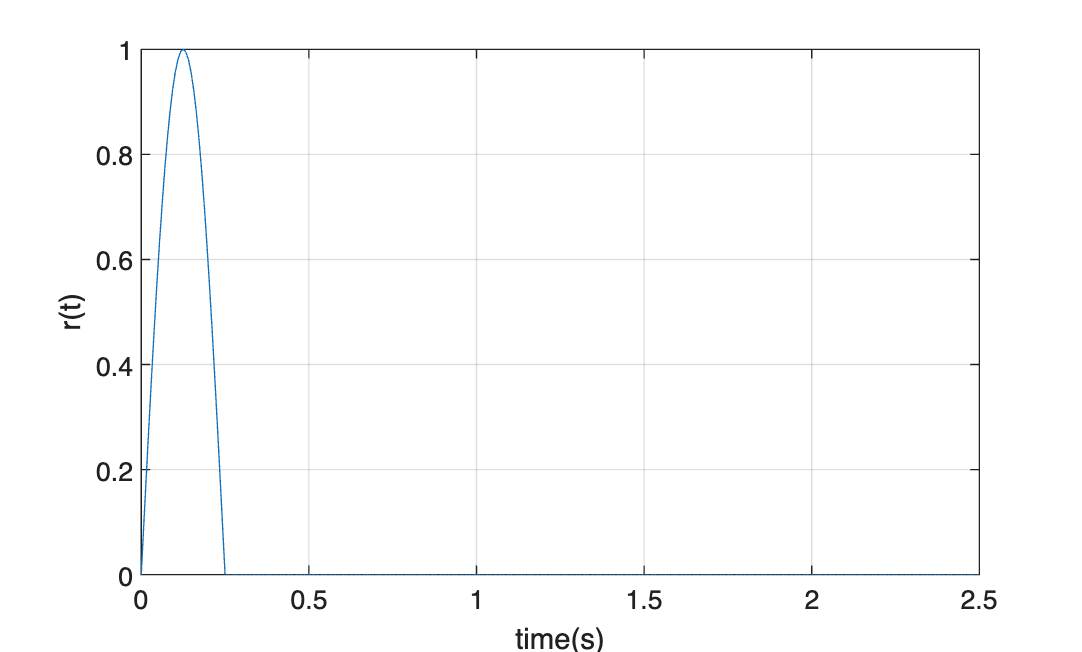

t2 = [t1(end)+ delt:delt:5.0*pT]';
r2 = zeros(size(t2));

t1 = [t1;t2];
r1 = [r1;r2];
clear t2 r2

figure(2)
plot(t1,r1)
xlabel('time(s)')
ylabel('r(t)')
grid on

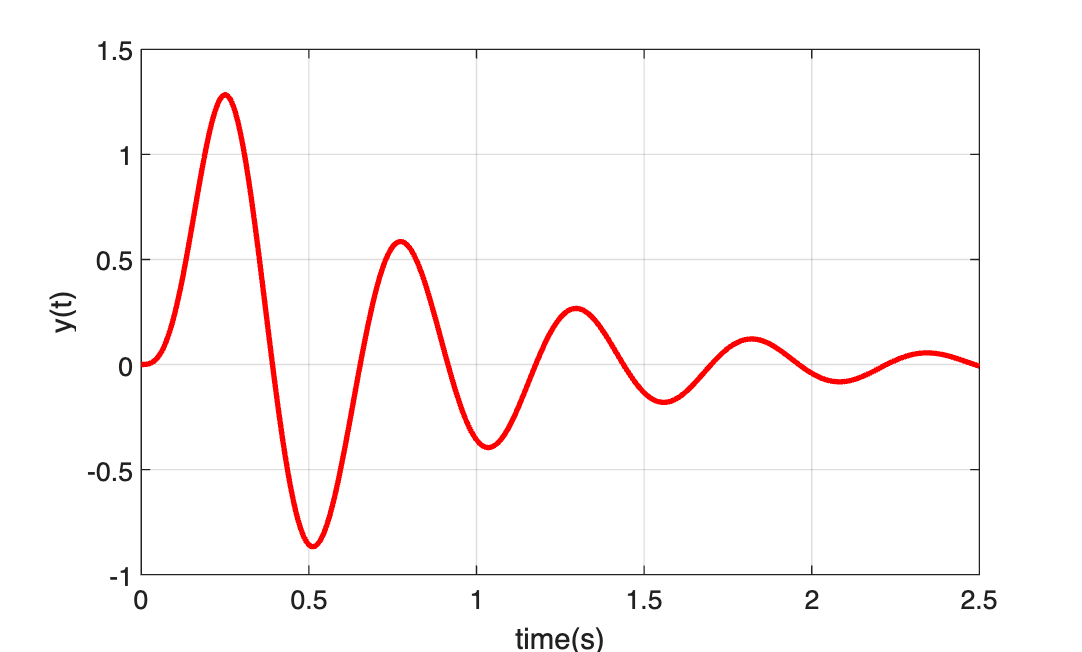


y1 = lsim(G,r1,t1);
figure(3)
plot(t1,y1,'r','LineWidth',2,'DisplayName','lsim')
xlabel('time(s)')
ylabel('y(t)')
grid on